# Actividad: Raíces de ecuaciones

`Nombre: Daniel Alfredo Barreras Meraz`

`Matrícula: A01254805`

`Fecha: 2 de mayo de 2023`

## Actividad 3. Equilibrio entre dos cargas.

El diagrama muestra un arreglo de dos cargas, una de 3μC en el origen, y una de -5μC en el

punto (0.5, m). Se quiere colocar una carga prueba en algún punto cercano a estas cargas de

manera que esté en equilibrio, es decir, que la suma de fuerzas sobre ella sea cero. 

### `A)`

% Parámetros del problema
q1 = 3e-6; 
q2 = -5e-6; 
distancia = 0.5; 
k = 8.99e9; 

% Función de la ecuación cuadrática
f = @(x) k*q1./x.^2 + k*q2./(distancia-x).^2;

% Derivada de la función
df = @(x) -2*k*q1./x.^3 + 2*k*q2./(d-x).^3;

% Valor inicial para el método de Newton-Raphson
x0 = 0.1;

% Método de Newton-Raphson para encontrar la raíz
tolerancia = 1e-4; 
max_iteraciones = 100; 
iteracion = 0;

while abs(f(x0)) > tolerancia && iter < max_iteraciones
    iteracion = iteracion + 1;
    x0 = x0 - f(x0)/df(x0);
end

if x0 < 0
    posicion = "A la izquiera";
elseif x0 > distancia
    posicion = "A la derecha";
else
    posicion = "Entre";
end

% Solución
fprintf('La carga prueba debe colocarse en x = %.4f metros\n(%s las dos cargas)', x0, posicion);

La carga prueba debe colocarse en x = 0.2182 metros
(Entre las dos cargas)

#### B)

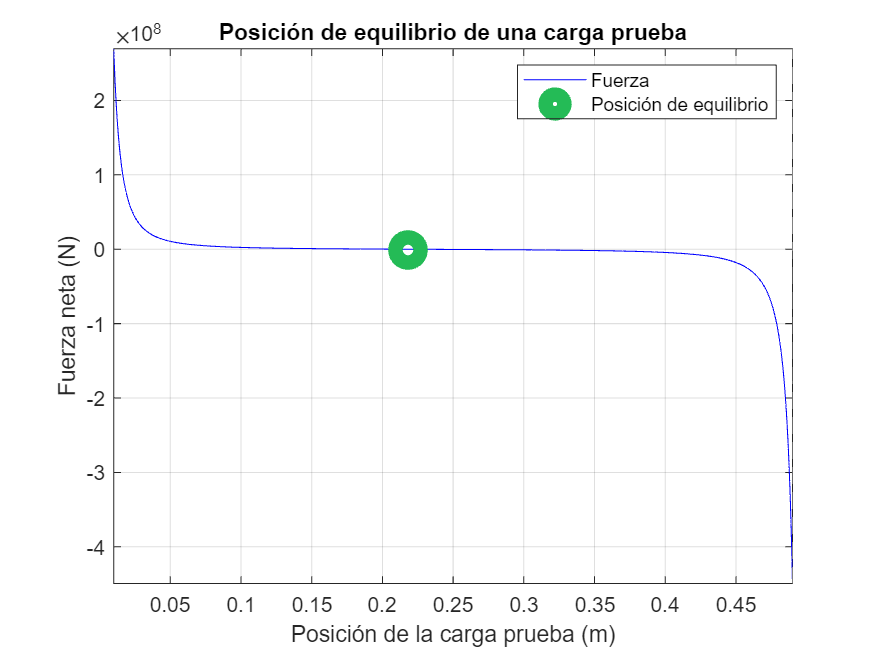

% Grafica la función
fplot(f, [0.01, 0.49], '-b');
grid on; hold on;
plot(x0, f(x0), 'or', 'MarkerSize', 12, 'LineWidth', 7, 'Color', "#24bb56");
xlabel('Posición de la carga prueba (m)'); ylabel('Fuerza neta (N)');
title('Posición de equilibrio de una carga prueba');
legend('Fuerza', 'Posición de equilibrio');